# TOF-Times

## Semi-Supervised Machine Learning Classification for Data from spICP-TOFMS: Cerium-Containing Nanoparticles Demo

Licenses required: matlab and statistics_toolbox

### Chapter 1 - Data Preprocessing

Data files (.csv) are exported from TOF-SPI and imported, here, as tables. All empty cells are filled with zeros and the variable names (1st row) are preserved. 

CeriumOxide = readtable("ElementMasses_LiqQuant_100x ENP_2022-08-23_11h52m13s.csv",'EmptyValue',0, ...
    'VariableNamingRule','preserve');
Ferrocerium = readtable("ElementMasses_LiqQuant_100x INP_2022-08-23_10h11m12s.csv",'EmptyValue',0, ...
    'VariableNamingRule','preserve');
Bastnaesite = readtable("ElementMasses_LiqQuant_250X NNP_2022-08-23_11h04m28s.csv",'EmptyValue',0, ...
    'VariableNamingRule','preserve');
disp('CSVs successfully read.')

CSVs successfully read.


The first two columns (index and timestamp (s)) are separated from the numeric data as they are not necessary in classifying particle events.

CeriumOxide_SI = CeriumOxide(:,1:2); %Add columns to their own variable
CeriumOxide = CeriumOxide(:,3:end); %Remove columns from initial table
Ferrocerium_SI = Ferrocerium(:,1:2);
Ferrocerium = Ferrocerium(:,3:end);
Bastnaesite_SI = Bastnaesite(:,1:2);
Bastnaesite = Bastnaesite(:,3:end);
disp('Additional particle information removed. See _SI variables.')

Additional particle information removed. See _SI variables.


The numeric data is then truncated at 4.90E-17 (49 ag), the critical mass of cerium for the ferrocerium pristine sample. This value was selected because it was, relatively, the largest of the three particle types.

BelowCritMass = table(); %Empty table
x = 1; %Used as indexing value

for i = 1:1:height(CeriumOxide) %Height is used instead of length because data is formatted as a table
    if CeriumOxide{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass(x,:) = CeriumOxide(i,:); %Adds the row to the new table
        x = x + 1;
    end
end
[idx,~] = find(CeriumOxide{:,"Ce (g)"} <= (4.89727180868979E-17));%Records the row indexes of Ce values below the critical mass
CeriumOxide(idx,:) = []; %Deletes rows from primary table that are below the critical mass

for i = 1:1:height(Ferrocerium)
    if Ferrocerium{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass(x,:) = Ferrocerium(i,:);
        x = x + 1;
    end 
end
[idx,~] = find(Ferrocerium{:,"Ce (g)"} <= (4.89727180868979E-17));
Ferrocerium(idx,:) = [];

for i = 1:1:height(Bastnaesite)
    if Bastnaesite{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass(x,:) = Bastnaesite(i,:);
        x = x + 1;
    end 
end
[idx,~] = find(Bastnaesite{:,"Ce (g)"} <= (4.89727180868979E-17));
Bastnaesite(idx,:) = [];
idx = [];
disp('Pristine suspension data successfully preprocessed.')

Pristine suspension data successfully preprocessed.


### Chapter 2 - Training Sets

The data that will be assigned labels is randomly sampled from all of the pristine samples. Preliminary classes are assigned based on the sample from which they originated; i.e. a cerium particle events from the CeriumOxide table will be 'classified' as an engineered nanoparticle (ENP).

p = randsample(height(CeriumOxide),400,true); %Sampling row indices
q = randsample(height(Ferrocerium),400,true);
r = randsample(height(Bastnaesite),400,true);
lblNNP = table();
lblINP = table();
lblENP = table();

for i = 1:1:400
    lblENP(i,:) = CeriumOxide(p(i),:); %Add the selected row to a table
    lblINP(i,:) = Ferrocerium(q(i),:);
    lblNNP(i,:) = Bastnaesite(r(i),:);
end
for i = 1:1:400
    lblENP.Ptype{i} = 'ENP'; %Assign appropriate class to the data
    lblINP.Ptype{i} = 'INP';
    lblNNP.Ptype{i} = 'NNP';
end

The randomly sampled data from the pristine suspensions are concatenated, the labels are added to a new table and the raw data from all three representatives are concatenated into one table as the 'unlabeled' data.

lblDataTrain = vertcat(lblENP,lblINP, lblNNP); %Concatenate all the labeled data into one table
TrueClass = lblDataTrain.Ptype; %Add the paticle types to a separate table
lblDataTrain.Ptype = []; %Delete the particle types from the table
unlblDataTrain = vertcat(CeriumOxide, Ferrocerium, Bastnaesite); %Unlabled training data
disp('Training data successfully generated.')

Training data successfully generated.


### Chapter 3 - Building the Machine Learning Model

The semi-supervised learning model uses both an ensemble and tree template. The decision tree utilizes all default settings with the exception of setting the tree to be reproducible.  

t = templateTree('Reproducible', true);

A bagged classification ensemble is defined with 500 learning cycles, all other parameters are default. 

ens_temp = templateEnsemble("Bag",500,t,"Type","Classification");

The randomly sampled numeric data, sample classes and the unlabled training data is fed into the

Mdl = fitsemiself(lblDataTrain, TrueClass, unlblDataTrain, Learner=ens_temp);
disp('Model 1 successfully trained. Ready for classification.')

Model 1 successfully trained. Ready for classification.


The model is used to predict labels for the labled training data. This is done because we predefined the labels and will have something to compare our results to.

First_Prediction = predict(Mdl, lblDataTrain);

The predicted classes and true classes are directly compared in a confusion matrix.

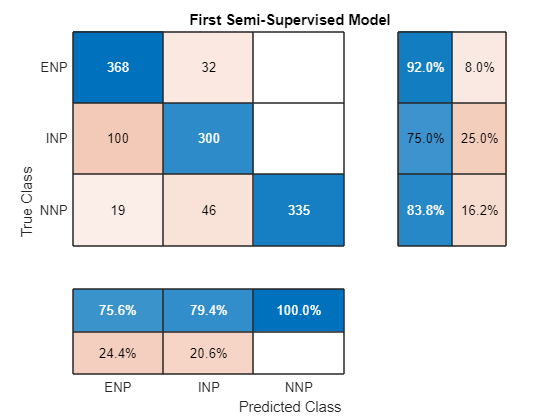

confusionchart(TrueClass,First_Prediction,'RowSummary','row-normalized','ColumnSummary','column-normalized')
title('First Semi-Supervised Model')

Classification predictions are made for the unlabled data for later comparison of the performance characterization. 'True labels' are assigned to each particle event to keep track of where the particle events originated.

Test_Pred = predict(Mdl,unlblDataTrain); %Predict labels for unlabled data
for i = 1:1:height(CeriumOxide)
    PtypeENP{i,1} = 'ENP'; %Assign appropriate 'true' class to the data
end
for i = 1:1:height(Ferrocerium)
    PtypeINP{i,1} = 'INP'; 
end
for i = 1:1:height(Bastnaesite)
    PtypeNNP{i,1} = 'NNP';
end
unlblTrueClass = vertcat(PtypeNNP,PtypeINP,PtypeENP); %Concatenate 'true' labels

### Chapter 4 - Relabeling and Resampling

New variables are defined and data is once again concatenated into one table (for convenience).

MisclassifiedPtcls = table();
CorrClassifiedPtcls = table();
[s,t] = deal(1); %Will be used as row indices
CompleteData =  [First_Prediction(:,1),TrueClass(:,1),lblDataTrain(:,:)]; %Concatenate the data into one table
CompleteData.Properties.VariableNames = ["Pred.Class", "TrueClass", "Fe (g)",...
    "La (g)","Ce (g)","Th (g)","Nd (g)", "Pr (g)"]; %Set variable names
disp('Beginning to sort data by classification...')

Beginning to sort data by classification...


The predicted and true class strings are compared. If they are the different then the row of data is added to the misclassified table; if they are the same then they are added to the correctly classified table. A new variable, ModifiedClass, is established. The predicted class is used to create the undefined classifications. If a particle was misclassified and its predicted label was ENP, then it's modified class is undefined engineered (UNE), etc.

UNE = table();
UNI = table();
UNN = table();
ENP = table();
INP = table();
NNP = table();
[a,b,c,d,e,f] = deal(1);

for i = 1:1:height(CompleteData) %Index down the rows
    if strcmpi(CompleteData{i,1},CompleteData{i,2}) == 0 %If the predicted and true classes are not the same
        if strcmpi(CompleteData{i,"Pred.Class"}, 'ENP') == 1 %If the predicted class is 'ENP'
            CompleteData(i,"ModifiedClass") = {'UNE'}; %Assign a new classification of 'UNE' to the variable 'ModifiedClass'
            UNE(a,:) = CompleteData(i,:); %Add the raw values to the UNE table
            a = a + 1; %Increase the row index
        elseif strcmpi(CompleteData{i,"Pred.Class"}, 'INP') == 1 %If the predicted class is 'INP'
            CompleteData(i,"ModifiedClass") = {'UNI'}; %Assign a new classification of 'UNI' to the variable 'ModifiedClass'
            UNI(b,:) = CompleteData(i,:);
            b = b + 1;
        else %If the predicted class is 'NNP'
            CompleteData(i,"ModifiedClass") = {'UNN'}; %Assign a new classification of 'UNN' to the variable 'ModifiedClass'
            UNN(c,:) = CompleteData(i,:); %#ok<*SAGROW>
            c = c + 1;
        end
    else %If the predicted and true classes are the same
        CompleteData(i,"ModifiedClass") = CompleteData{i,"TrueClass"}; %Assign the value in the 'TrueClass' to the 'ModifiedClass' 
        if strcmpi(CompleteData{i,"Pred.Class"}, 'ENP') == 1 %If the predicted class if 'ENP'
            ENP(d,:) = CompleteData(i,:); %Assign the raw values to the ENP table
            d = d + 1;
        elseif strcmpi(CompleteData{i,"Pred.Class"}, 'INP') == 1 %If the predicted class if 'INP'
            INP(e,:) = CompleteData(i,:);%Assign the raw values to the INP table
            e = e + 1;
        else %If the predicted class if 'NNP'
            NNP(f,:) = CompleteData(i,:); %Assign the raw values to the NNP table
            f = f + 1;
        end
    end
end

disp('Data sucessfully sorted. Beginning resampling...')

Data sucessfully sorted. Beginning resampling...


Each new sample class is randomly sampled 400 times to ensure that there is no additional weighting added into the model based on number of observations.

msg = 'No undefined particles of this type. Proceeding without this class.';
%Resampling the unclassifiable classes
if isempty(UNE) == 0 %If the table is not empty
    d = randsample(height(UNE),400,true); %Sample the row indices
    smpldUNE = table();
    for i = 1:1:400
        smpldUNE(i,:) = UNE(d(i),:); %Assign the randomly sampled rows to the new table
    end
else
    warning(msg) %Otherwise, display an error message
end
if isempty(UNI) == 0
    e = randsample(height(UNI),400,true);
    smpldUNI = table();
    for i = 1:1:400
        smpldUNI(i,:) = UNI(e(i),:);
    end
else
    warning(msg)
end
if isempty(UNN) == 0
    f = randsample(height(UNN),400,true);
    smpldUNN = table();
    for i = 1:1:400
        smpldUNN(i,:) = UNN(f(i),:);
    end
else
    warning(msg)
end

%Resampling the original classes
x = randsample(height(ENP),400,true);
y = randsample(height(INP),400,true);
z = randsample(height(NNP),400,true);
for i = 1:1:400
    Resampled_CorrClass(i,:) = ENP(x(i),:);
    Resampled_CorrClass(i+400,:) = INP(y(i),:);
    Resampled_CorrClass(i+800,:) = NNP(z(i),:);
end
disp('Resampling sucessfully completed.')

Resampling sucessfully completed.


The resampled data is then parsed out into different variable names and used for the training of the second model.

Resampled_CorrClass.Properties.VariableNames = smpldUNE.Properties.VariableNames; %Set the variable names
Resampled_CorrClass.ModifiedClass = Resampled_CorrClass(:, "TrueClass");
lblDataRetrain = vertcat(Resampled_CorrClass(:,3:8),smpldUNE(:,3:8),smpldUNI(:,3:8)); %Concatenate the resampled events
ModClass = table2array(vertcat(Resampled_CorrClass(:,9),smpldUNE(:,9),smpldUNI(:,9))); %Define the modified class variable
FTPred = vertcat(Resampled_CorrClass(:,1),smpldUNE(:,1),smpldUNI(:,1)); %Record the predicted classes in another variable; this preserves the order
TrueClassRetrain = vertcat(Resampled_CorrClass(:,2),smpldUNE(:,2),smpldUNI(:,2)); %Record the true classes in another variable; this preserves the order
disp('All necessary variables sucessfully defined for the second training.')

All necessary variables sucessfully defined for the second training.


### Chapter 5 - Retraining

Mdl_retrain is established using the same parameters and learners as the first model. The second model is used to predict the classifications for the labled data.

Mdl_retrain = fitsemiself(lblDataRetrain,ModClass,unlblDataTrain,"Learner",ens_temp); %Train the second model
disp('Model 2 successfully trained. Ready for classification.')

Model 2 successfully trained. Ready for classification.


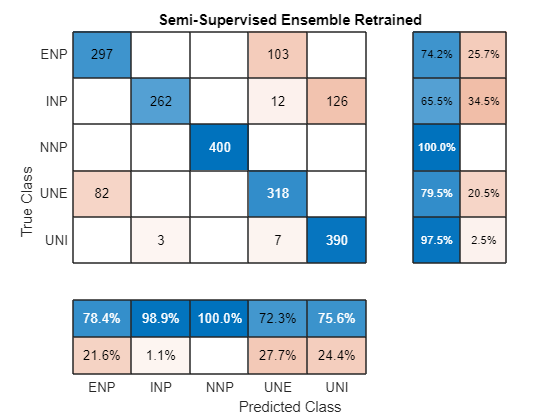

Second_Prediction = predict(Mdl_retrain, lblDataRetrain); %Predict the classes for the labeled data
confusionchart(ModClass{:,1}, Second_Prediction,'RowSummary','row-normalized','ColumnSummary','column-normalized')
title('Semi-Supervised Ensemble Retrained')

Test_Pred2 = predict(Mdl_retrain,unlblDataTrain); %For later comparison to the first model performance

### Chapter 6 - Predictions of Mixture Classifications

The second model was used to predict the classification labels for mixture samples in two cases. See the above sections for clarification on function usage.

#### Case 1: Increasing engineered nanoparticle concentrations with relatively constant background concentrations of incidental and natural nanoparticles.

Data files (.csv) are exported from TOF-SPI and imported, here, as tables. All empty cells are filled with zeros and the variable names (1st row) is preserved. The first two columns (index and timestamp (s)) are separated from the numeric data as they are not useful in identifying the particle classification.

E1 = readtable("ElementMasses_LiqQuant_E1_2022-08-23_12h50m12s.csv",'EmptyValue',0, 'VariableNamingRule', ...
    'preserve'); %Highest ENP concentration
E2 = readtable("ElementMasses_LiqQuant_E2_2022-08-23_12h57m20s.csv",'EmptyValue',0, 'VariableNamingRule', ...
    'preserve');
E3 = readtable("ElementMasses_LiqQuant_E3_2022-08-23_13h04m28s.csv",'EmptyValue',0, 'VariableNamingRule', ...
    'preserve');
E4 = readtable("ElementMasses_LiqQuant_E4_2022-08-23_13h11m37s.csv",'EmptyValue',0, 'VariableNamingRule', ...
    'preserve');
E5 = readtable("ElementMasses_LiqQuant_E5_2022-08-23_13h18m45s.csv",'EmptyValue',0, 'VariableNamingRule', ...
    'preserve');
E6 = readtable("ElementMasses_LiqQuant_E6_2022-08-23_13h25m53s.csv",'EmptyValue',0, 'VariableNamingRule', ...
    'preserve'); %Lowest ENP concentration
disp('Mixture data for Case 1 sucessfully read.')

Mixture data for Case 1 sucessfully read.


E1 = E1(:,3:end);
E2 = E2(:,3:end);
E3 = E3(:,3:end);
E4 = E4(:,3:end);
E5 = E5(:,3:end);
E6 = E6(:,3:end);

Mixture data was filtered at the critical mass to impose the same post-treatment as the training data.

BelowCritMass_Mixtures = table();
x = 1; 
for i = 1:1:height(E1) 
    if E1{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass_Mixtures(x,:) = E1(i,:); 
        x = x + 1;
    end
end
[idx,~] = find(E1{:,"Ce (g)"} <= (4.89727180868979E-17));
E1(idx,:) = [];
 
for i = 1:1:height(E2) 
    if E2{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass_Mixtures(x,:) = E2(i,:); 
        x = x + 1;
    end
end
[idx,~] = find(E2{:,"Ce (g)"} <= (4.89727180868979E-17));
E2(idx,:) = [];

for i = 1:1:height(E3) 
    if E3{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass_Mixtures(x,:) = E3(i,:); 
        x = x + 1;
    end
end
[idx,~] = find(E3{:,"Ce (g)"} <= (4.89727180868979E-17));
E3(idx,:) = [];

for i = 1:1:height(E4) 
    if E4{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass_Mixtures(x,:) = E4(i,:); 
        x = x + 1;
    end
end
[idx,~] = find(E4{:,"Ce (g)"} <= (4.89727180868979E-17));
E4(idx,:) = [];

for i = 1:1:height(E5) 
    if E5{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass_Mixtures(x,:) = E5(i,:); 
        x = x + 1;
    end
end
[idx,~] = find(E5{:,"Ce (g)"} <= (4.89727180868979E-17));
E5(idx,:) = [];

for i = 1:1:height(E6) 
    if E6{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass_Mixtures(x,:) = E6(i,:); 
        x = x + 1;
    end
end
[idx,~] = find(E6{:,"Ce (g)"} <= (4.89727180868979E-17));
E6(idx,:) = [];
disp('Mixture data for Case 1 sucessfully preprocessed. Beginning predictions...')

Mixture data for Case 1 sucessfully preprocessed. Beginning predictions...


Using the second model, classification labels are predicted for the mixture samples then plotted together as a bar chart.

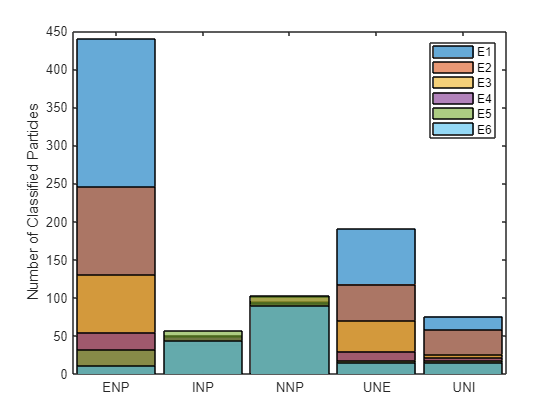

E1_pred = predict(Mdl_retrain,E1);
E2_pred = predict(Mdl_retrain,E2);
E3_pred = predict(Mdl_retrain,E3);
E4_pred = predict(Mdl_retrain,E4);
E5_pred = predict(Mdl_retrain,E5);
E6_pred = predict(Mdl_retrain,E6);
histogram(categorical(E1_pred),'DisplayName','E1')
hold on
histogram(categorical(E2_pred),'DisplayName','E2')
histogram(categorical(E3_pred),'DisplayName','E3')
histogram(categorical(E4_pred),'DisplayName','E4')
histogram(categorical(E5_pred),'DisplayName','E5')
histogram(categorical(E6_pred),'DisplayName','E6')
legend('show')
ylabel('Number of Classified Particles')
hold off

disp('Predictions for Case 1 completed.')

Predictions for Case 1 completed.


#### Case 2: Increasing increasing nanoparticle concentrations with relatively constant background concentrations of engineered and natural nanoparticles.

For case 2, the data is processed in the same manner as case 1.

I1 = readtable("ElementMasses_LiqQuant_I1_2022-08-23_13h33m01s.csv",'EmptyValue',0, 'VariableNamingRule', ...
    'preserve'); %Highest INP concentration
I2 = readtable("ElementMasses_LiqQuant_I2_2022-08-23_13h40m09s.csv",'EmptyValue',0, 'VariableNamingRule', ...
    'preserve');
I3 = readtable("ElementMasses_LiqQuant_I3_2022-08-23_13h47m17s.csv",'EmptyValue',0, 'VariableNamingRule', ...
    'preserve');
I4 = readtable("ElementMasses_LiqQuant_I4_2022-08-23_13h54m25s.csv",'EmptyValue',0, 'VariableNamingRule', ...
    'preserve');
I5 = readtable("ElementMasses_LiqQuant_I5_2022-08-23_14h01m33s.csv",'EmptyValue',0, 'VariableNamingRule', ...
    'preserve');
I6 = readtable("ElementMasses_LiqQuant_I6_2022-08-23_14h08m41s.csv",'EmptyValue',0, 'VariableNamingRule', ...
    'preserve');%Lowest INP Concentration
disp('Mixture data for Case 2 sucessfully read.')

Mixture data for Case 2 sucessfully read.


I1 = I1(:,3:end);
I2 = I2(:,3:end);
I3 = I3(:,3:end);
I4 = I4(:,3:end);
I5 = I5(:,3:end);
I6 = I6(:,3:end);

for i = 1:1:height(I1) 
    if I1{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass_Mixtures(x,:) = I1(i,:); 
        x = x + 1;
    end
end
[idx,~] = find(I1{:,"Ce (g)"} <= (4.89727180868979E-17));
I1(idx,:) = [];
 
for i = 1:1:height(I2) 
    if I2{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass_Mixtures(x,:) = I2(i,:); 
        x = x + 1;
    end
end
[idx,~] = find(I2{:,"Ce (g)"} <= (4.89727180868979E-17));
I2(idx,:) = [];

for i = 1:1:height(I3) 
    if I3{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass_Mixtures(x,:) = I3(i,:); 
        x = x + 1;
    end
end
[idx,~] = find(I3{:,"Ce (g)"} <= (4.89727180868979E-17));
I3(idx,:) = [];

for i = 1:1:height(I4) 
    if I4{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass_Mixtures(x,:) = I4(i,:); 
        x = x + 1;
    end
end
[idx,~] = find(I4{:,"Ce (g)"} <= (4.89727180868979E-17));
I4(idx,:) = [];

for i = 1:1:height(I5) 
    if I5{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass_Mixtures(x,:) = I5(i,:); 
        x = x + 1;
    end
end
[idx,~] = find(I5{:,"Ce (g)"} <= (4.89727180868979E-17));
I5(idx,:) = [];

for i = 1:1:height(I6) 
    if I6{i,"Ce (g)"} <= (4.89727180868979E-17)
        BelowCritMass_Mixtures(x,:) = I6(i,:); 
        x = x + 1;
    end
end
[idx,~] = find(I6{:,"Ce (g)"} <= (4.89727180868979E-17));
I6(idx,:) = [];
disp('Mixture data for Case 2 sucessfully preprocessed. Beginning predictions...')

Mixture data for Case 2 sucessfully preprocessed. Beginning predictions...


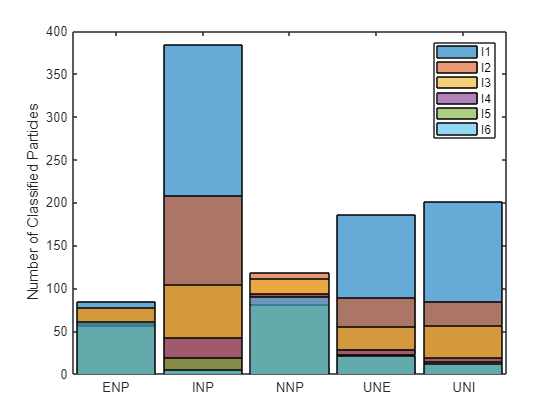

I1_pred = predict(Mdl_retrain,I1);
I2_pred = predict(Mdl_retrain,I2);
I3_pred = predict(Mdl_retrain,I3);
I4_pred = predict(Mdl_retrain,I4);
I5_pred = predict(Mdl_retrain,I5);
I6_pred = predict(Mdl_retrain,I6);
histogram(categorical(I1_pred),'DisplayName','I1')
hold on
histogram(categorical(I2_pred),'DisplayName','I2')
histogram(categorical(I3_pred),'DisplayName','I3')
histogram(categorical(I4_pred),'DisplayName','I4')
histogram(categorical(I5_pred),'DisplayName','I5')
histogram(categorical(I6_pred),'DisplayName','I6')
legend('show')
ylabel('Number of Classified Particles')
hold off

disp('Predictions for Case 2 completed.')

Predictions for Case 2 completed.


disp('Thank you for using TOF-Times! Processing of particle data has been sucessfully completed.')

Thank you for using TOF-Times! Processing of particle data has been sucessfully completed.


disp('To export classifications, please use the Workspace.')

To export classifications, please use the Workspace.


disp('The following licenses were used in this machine learning workflow:')

The following licenses were used in this machine learning workflow:


license('inuse')

matlab
statistics_toolbox


### Appendix

The following two sections calculate the figures of merit of the first and second models, respectively. 

chart1 = confusionmat(TrueClass(:,1), First_Prediction(:,1)); %Confusion matrix for the first model
tp = [];
fp = [];
fn = [];
tn = [];
len = size(chart1,1); %Length of the first matrix
for k = 1:len
    tp_value = chart1(k,k);
    tp = [tp, tp_value]; %Calculating the true postives

    fp_value = sum(chart1(:,k))-tp_value;
    fp = [fp, fp_value]; %Calculating the false positives

    fn_value = sum(chart1(k,:)) - tp_value;
    fn = [fn, fn_value]; %Calculating the false negatives

    tn_value = sum(sum(chart1)) - (tp_value + fp_value + fn_value);
    tn = [tn, tn_value]; %Calculating the true negatives
end

prec = tp ./ (tp+fp); %Precision
sens = tp ./ (tp+fn); %Sensitivity
spec = tn ./ (tn+fp); %Specificity
acc = sum(tp) ./ sum(sum(chart1)); %Accuracy for MULTIClass system
f1 = (2 .* prec .* sens)./(prec + sens); %F1 measure
name = ["true_positive"; "false_positive"; "false_negative"; "true_negative"; ...
    "precision"; "sensitivity"; "specificity"; "accuracy"; "F-measure"]; %Variable names
varNames = ["name"; "classes"];
values = [tp; fp; fn; tn; prec; sens; spec; repmat(acc, 1, len); f1]; %Fill in the table
stats = table(name, values, 'VariableNames',varNames) %First model figures of merit

stats = 9×2 table
          name                     classes           
    ________________    _____________________________

    "true_positive"         368        300        335
    "false_positive"        119         78          0
    "false_negative"         32        100         65
    "true_negative"         681        722        800
    "precision"         0.75565    0.79365          1
    "sensitivity"          0.92       0.75     0.8375
    "specificity"       0.85125     0.9025          1
    "accuracy"          0.83583    0.83583    0.83583
    "F-measure"         0.82976    0.77121    0.91156


Calculation of the figures of merit for the second model with the normalized confusion matrix.Please see the above annotations for more context.

chart2 = confusionmat(ModClass{:,1}, Second_Prediction);
for i = 1:1:5 %Normalize the confusion matrix for resampling
    chart2(1,i) = (chart2(1,i)*chart1(3,3))/400; %ENP
    chart2(2,i) = (chart2(2,i)*chart1(2,2))/400; %INP
    chart2(3,i) = (chart2(3,i)*chart1(1,1))/400; %NNP
    chart2(4,i) = (chart2(4,i)*(chart1(2,3)+chart1(1,3)))/400; %UNE
    chart2(5,i) = (chart2(5,i)*(chart1(1,2)+chart1(3,2)))/400; %UNI
end
tp = [];
fp = [];
fn = [];
tn = [];
len = size(chart2,1);
for k = 1:len
    tp_value = chart2(k,k);
    tp = [tp, tp_value];

    fp_value = sum(chart2(:,k))-tp_value;
    fp = [fp, fp_value];

    fn_value = sum(chart2(k,:)) - tp_value;
    fn = [fn, fn_value];

    tn_value = sum(sum(chart2)) - (tp_value + fp_value + fn_value);
    tn = [tn, tn_value];
end

prec = tp ./ (tp+fp);
sens = tp ./ (tp+fn);
spec = tn ./ (tn+fp);
acc = sum(tp) ./ sum(sum(chart2));
f1 = (2 .* prec .* sens)./(prec + sens);
name = ["true_positive"; "false_positive"; "false_negative"; "true_negative"; ...
    "precision"; "sensitivity"; "specificity"; "accuracy"; "F-measure"];
varNames = ["name"; "classes"];
values = [tp; fp; fn; tn; prec; sens; spec; repmat(acc, 1, len); f1];
stats = table(name, values, 'VariableNames',varNames) %Second model figures of merit

stats = 9×2 table
          name                                classes                      
    ________________    ___________________________________________________

    "true_positive"      248.74      196.5        368          0      76.05
    "false_positive"          0      0.585          0     96.627       94.5
    "false_negative"     86.262      103.5          0          0       1.95
    "true_negative"         746     780.41        713     984.37      908.5
    "precision"               1    0.99703          1          0    0.44591
    "sensitivity"        0.7425      0.655          1        NaN      0.975
    "specificity"             1    0.99925          1    0.91061    0.90578
    "accuracy"          0.82265    0.82265    0.82265    0.82265    0.82265
    "F-measure"         0.85222    0.79061          1        NaN    0.61195


ROC Curve for the first machine learning model based on the classifications of the unlabled training data.

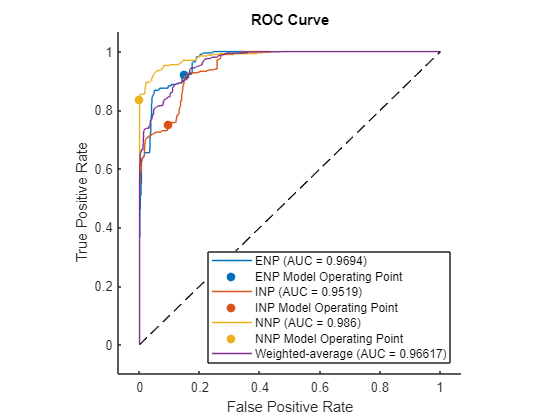

[~,scrs1] = predict(Mdl,lblDataTrain);
rocObj1 = rocmetrics(TrueClass,scrs1,Mdl.ClassNames,"AdditionalMetrics","accu"); %First model ROC Curve
curveObj1 = plot(rocObj1,'AverageROCType','weighted');

ROC Curve for the first machine learning model based on the classifications of the unlabled training data.

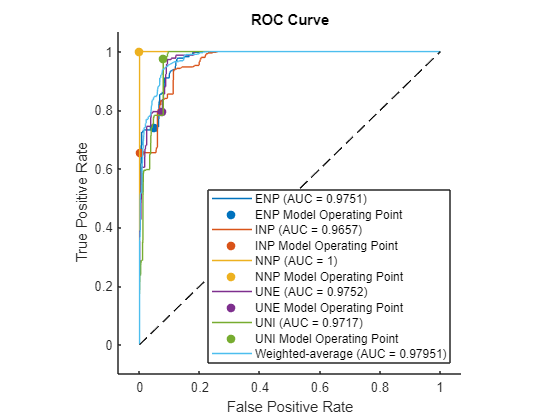

[~,scrs2] = predict(Mdl_retrain,lblDataRetrain);
rocObj2 = rocmetrics(table2array(ModClass),scrs2,Mdl_retrain.ClassNames,"AdditionalMetrics","accu"); %First model ROC Curve
curveObj2 = plot(rocObj2,'AverageROCType','weighted');

Please see the following copyright information used for the calculations of the figures of merit.

% Copyright (c) 2021, Eugenio Bertolini
% All rights reserved.
% 
% Redistribution and use in source and binary forms, with or without
% modification, are permitted provided that the following conditions are met:
% 
% * Redistributions of source code must retain the above copyright notice, this
%   list of conditions and the following disclaimer.
% 
% * Redistributions in binary form must reproduce the above copyright notice,
%   this list of conditions and the following disclaimer in the documentation
%   and/or other materials provided with the distribution
% 
% * Neither the name of  nor the names of its
%   contributors may be used to endorse or promote products derived from this
%   software without specific prior written permission.
% 
% THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS"
% AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT LIMITED TO, THE
% IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE ARE
% DISCLAIMED. IN NO EVENT SHALL THE COPYRIGHT OWNER OR CONTRIBUTORS BE LIABLE
% FOR ANY DIRECT, INDIRECT, INCIDENTAL, SPECIAL, EXEMPLARY, OR CONSEQUENTIAL
% DAMAGES (INCLUDING, BUT NOT LIMITED TO, PROCUREMENT OF SUBSTITUTE GOODS OR
% SERVICES; LOSS OF USE, DATA, OR PROFITS; OR BUSINESS INTERRUPTION) HOWEVER
% CAUSED AND ON ANY THEORY OF LIABILITY, WHETHER IN CONTRACT, STRICT LIABILITY,
% OR TORT (INCLUDING NEGLIGENCE OR OTHERWISE) ARISING IN ANY WAY OUT OF THE USE
% OF THIS SOFTWARE, EVEN IF ADVISED OF THE POSSIBILITY OF SUCH DAMAGE.